Rm = 0.625;
Rf = 1;
RR = Rm + Rf;
beta = deg2rad(60);
H = 0.5;
% x_f
x_fb = [RR*cos(2*beta),...   
         RR*cos(1*beta),...
         RR*cos(3*beta),...
         RR*cos(0*beta), ...
         RR*cos(4*beta), ...
         RR*cos(5*beta)]'

x_fb =    -0.8125
    0.8125
   -1.6250
    1.6250
   -0.8125
    0.8125



y_off = [RR*sin(2*beta),...   
         RR*sin(1*beta),...
         RR*sin(3*beta),...
         RR*sin(0*beta), ...
         RR*sin(4*beta), ...
         RR*sin(5*beta)]'

y_off =     1.4073
    1.4073
    0.0000
         0
   -1.4073
   -1.4073



L = 0.75;
v = 1.5;
B = 0.5

B = 0.5000



T = L/v; %(s) Cycle Time
T_swing = (1-B)*T; %Transfer Time
T_support = B*T; % Support Time
dt = T_swing/6

dt = 0.0417


% Swing Phase:
y_dot_max = L/(3*dt); %(m/s) Max transfer speed in X
z_dot_max = y_dot_max %(m/s) Max transfer speed in Z (assumption)

z_dot_max = 6

y_ddot_max = y_dot_max/dt %(m/s^2) Max transfer acceleration in X

y_ddot_max = 144

z_ddot_max = z_dot_max/dt %(m/s^2) Max transfer acceleration in Z

z_ddot_max = 144


% Support Phase:
ys_dot_max = L/(5*dt); % (m/s) Max support phase in X
zs_dot_max = 0; % (m/s) Max support speed in Z (leg doesn't lift off ground)
ys_ddot_max = ys_dot_max/dt; % (m/s^2) Max transfer acceleration in X
zs_ddot_max = zs_dot_max/dt; % (m/s^2) Max transfer acceleration in Z (leg doesn't lift off the ground)

%Y-direction:
y_ddot_fg_pts = [0 y_ddot_max 0 0 -y_ddot_max 0 0];

y_dot_fg_pts = zeros(1,7);

for i = 1:6
    y_dot_fg_pts(i+1) = y_dot_fg_pts(i) + y_ddot_fg_pts(i)*dt; 
end

% Stance phase:
%Y-direction:
ys_ddot_fg_pts = [-ys_ddot_max 0 0 0 0 ys_ddot_max 0  ];
ys_dot_fg_pts = zeros(1,7);


for i = 1:6
   ys_dot_fg_pts(i+1) = ys_dot_fg_pts(i) + ys_ddot_fg_pts(i)*dt;
end

%Horizontal Movement of the foot with respect to ground (y_fg):
y_fg_pts = zeros(1,7);
ys_fg_pts = zeros(1,7);

y_fg_pts(1) = -L/2;
ys_fg_pts(1) = L/2;

for i = 1:6
    y_fg_pts(i+1) = y_fg_pts(i) + y_dot_fg_pts(i)*dt + (1/2)*y_ddot_fg_pts(i)*dt^2;
    ys_fg_pts(i+1) = ys_fg_pts(i) + ys_dot_fg_pts(i)*dt + (1/2)*ys_ddot_fg_pts(i)*dt^2;
end


Y = [y_fg_pts;y_dot_fg_pts; y_ddot_fg_pts]

Y =    -0.3750   -0.3750   -0.2500         0    0.2500    0.3750    0.3750
         0         0    6.0000    6.0000    6.0000         0         0
         0  144.0000         0         0 -144.0000         0         0


Ys = [ys_fg_pts; ys_dot_fg_pts; ys_ddot_fg_pts]

Ys =     0.3750    0.3000    0.1500   -0.0000   -0.1500   -0.3000   -0.3750
         0   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000         0
  -86.4000         0         0         0         0   86.4000         0



%Z-direction:
z_ddot_fg_pts = [z_ddot_max -z_ddot_max 0 0 -z_ddot_max z_ddot_max 0];
z_dot_fg_pts = zeros(1,7);

for i = 1:6
    z_dot_fg_pts(i+1) = z_dot_fg_pts(i) + z_ddot_fg_pts(i)*dt ;
end

%Vertical Movement of the foot with respect to ground (z_fg):
z_fg_pts = zeros(1,7);
zs_fg_pts = zeros(1,7);

for i = 1:6
    z_fg_pts(i+1) = z_fg_pts(i) + z_dot_fg_pts(i)*dt + (1/2)*z_ddot_fg_pts(i)*dt^2;
end

% Stance phase:
%Z-direction:
zs_ddot_fg_pts = [0 0 0 0 0 0 0 ];
zs_dot_fg_pts = zeros(1,7);
for i = 1:6
    zs_dot_fg_pts(i+1) = zs_dot_fg_pts(i) + zs_ddot_fg_pts(i)*dt ;
end

Z = [z_fg_pts;z_dot_fg_pts; z_ddot_fg_pts]

Z =          0    0.1250    0.2500    0.2500    0.2500    0.1250         0
         0    6.0000         0         0         0   -6.0000         0
  144.0000 -144.0000         0         0 -144.0000  144.0000         0


Zs = [zs_fg_pts;zs_dot_fg_pts; zs_ddot_fg_pts]

Zs =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0



X = zeros(3,length(Z))

X =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


Xs = zeros(3,length(Zs))

Xs =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0



tpts = 0:dt:T_swing

tpts =          0    0.0417    0.0833    0.1250    0.1667    0.2083    0.2500


tvec = linspace(0,T_swing,50)

tvec =          0    0.0051    0.0102    0.0153    0.0204    0.0255    0.0306    0.0357    0.0408    0.0459    0.0510    0.0561    0.0612    0.0663    0.0714    0.0765    0.0816    0.0867    0.0918    0.0969    0.1020    0.1071    0.1122    0.1173    0.1224    0.1276    0.1327    0.1378    0.1429    0.1480    0.1531    0.1582    0.1633    0.1684    0.1735    0.1786    0.1837    0.1888    0.1939    0.1990    0.2041    0.2092    0.2143    0.2194    0.2245    0.2296    0.2347    0.2398    0.2449    0.2500


[q, qd, qdd, pp] = cubicpolytraj([X(1,:);Y(1,:);Z(1,:)], tpts, tvec,"VelocityBoundaryCondition",[X(2,:);Y(2,:);Z(2,:)])

q =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3737   -0.3687   -0.3600   -0.3475   -0.3312   -0.3112   -0.2875   -0.2600   -0.2296   -0.1990   -0.1684   -0.1378   -0.1071   -0.0765   -0.0459   -0.0153    0.0153    0.0459    0.0765    0.1071    0.1378    0.1684    0.1990    0.2296    0.2600    0.2875    0.3112    0.3312    0.3475    0.3600    0.3687    0.3737    0.3750    0.3750    0.3750    0.3750    0.3750    0.3750    0.3750    0.3750    0

qd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.6122    1.3469    2.0816    2.8163    3.5510    4.2857    5.0204    5.7551    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    5.7551    5.0204    4.2857    3.5510    2.8163    2.0816    1.3469    0.6122         0         0         0         0         0         0         0         0    

qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000         0         0         0         0         0         0         0         0   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000 -144.0000 -144.0000 -144.0000 -144.0000 -144.0000 -144.0000 -144.0000 -144.0000         0         0         0         0         0         0         0         0   

pp = struct with fields:
      form: 'pp'
    breaks: [-1 0 0.0417 0.0833 0.1250 0.1667 0.2083 0.2500 1.2500]
     coefs: [24×4 double]
    pieces: 8
     order: 4
       dim: 3



[qs, qds, qdds, pps] = cubicpolytraj([Xs(1,:);Ys(1,:);Zs(1,:)], tpts, tvec,"VelocityBoundaryCondition",[Xs(2,:);Ys(2,:);Zs(2,:)])

qs =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3750    0.3739    0.3705    0.3649    0.3570    0.3469    0.3345    0.3199    0.3030    0.2847    0.2663    0.2480    0.2296    0.2112    0.1929    0.1745    0.1561    0.1378    0.1194    0.1010    0.0827    0.0643    0.0459    0.0276    0.0092   -0.0092   -0.0276   -0.0459   -0.0643   -0.0827   -0.1010   -0.1194   -0.1378   -0.1561   -0.1745   -0.1929   -0.2112   -0.2296   -0.2480   -0.2663   -0.2847   -0.3030   -0.3199   -0.3345   -0.3469   -0.3570   -0.3649   -0.3705   -0.3739   -

qds =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.4408   -0.8816   -1.3224   -1.7633   -2.2041   -2.6449   -3.0857   -3.5265   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000   -3.5265   -3.0857   -2.6449   -2.2041   -1.7633   -1.3224   -0.8816   -0.4408   

qdds =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -86.4000  -86.4000  -86.4000  -86.4000  -86.4000  -86.4000  -86.4000  -86.4000  -86.4000         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   86.4000   86.4000   86.4000   86.4000   86.4000   86.4000   86.4000   86.4000  

pps = struct with fields:
      form: 'pp'
    breaks: [-1 0 0.0417 0.0833 0.1250 0.1667 0.2083 0.2500 1.2500]
     coefs: [24×4 double]
    pieces: 8
     order: 4
       dim: 3


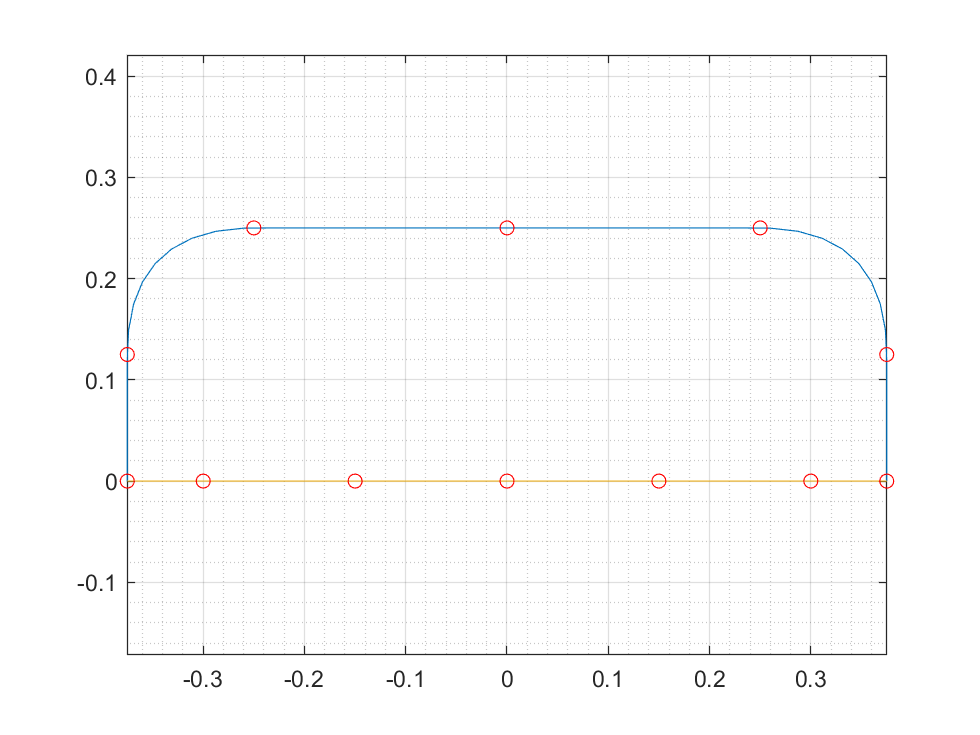


figure()
plot(q(2,:),q(3,:),y_fg_pts,z_fg_pts,'or')
hold on
plot(qs(2,:),qs(3,:),ys_fg_pts,zs_fg_pts,'or')
axis equal
grid on
grid minor

% qr = Rotx(deg2rad(35))*q

[r,c] = size(q(2,:));
((1-B)/2)*L

ans = 0.1875

C_y_bg = ones(r,c)*-((1-B)/2)*L

C_y_bg =    -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875


C_z_bg = ones(r,c)*H

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000



C_ys_bg = ones(r,c)*-((1-B)/2)*L;
C_zs_bg = ones(r,c)*H;

ydot_bg=v;
zdot_bg=0;

C_y_bg=C_y_bg+ydot_bg*ones(1,length(tvec)).*tvec

C_y_bg =    -0.1875   -0.1798   -0.1722   -0.1645   -0.1569   -0.1492   -0.1416   -0.1339   -0.1263   -0.1186   -0.1110   -0.1033   -0.0957   -0.0880   -0.0804   -0.0727   -0.0651   -0.0574   -0.0497   -0.0421   -0.0344   -0.0268   -0.0191   -0.0115   -0.0038    0.0038    0.0115    0.0191    0.0268    0.0344    0.0421    0.0497    0.0574    0.0651    0.0727    0.0804    0.0880    0.0957    0.1033    0.1110    0.1186    0.1263    0.1339    0.1416    0.1492    0.1569    0.1645    0.1722    0.1798    0.1875


C_z_bg=C_z_bg+zdot_bg*ones(1,length(tvec)).*tvec

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000



C_y_fb = q(2,:) -C_y_bg

C_y_fb =    -0.1875   -0.1952   -0.2028   -0.2105   -0.2181   -0.2258   -0.2334   -0.2411   -0.2487   -0.2551   -0.2577   -0.2566   -0.2518   -0.2432   -0.2309   -0.2148   -0.1949   -0.1722   -0.1492   -0.1263   -0.1033   -0.0804   -0.0574   -0.0344   -0.0115    0.0115    0.0344    0.0574    0.0804    0.1033    0.1263    0.1492    0.1722    0.1949    0.2148    0.2309    0.2432    0.2518    0.2566    0.2577    0.2551    0.2487    0.2411    0.2334    0.2258    0.2181    0.2105    0.2028    0.1952    0.1875


C_z_fb = q(3,:) -C_z_bg

C_z_fb =    -0.5000   -0.4981   -0.4925   -0.4831   -0.4700   -0.4531   -0.4325   -0.4082   -0.3800   -0.3508   -0.3252   -0.3033   -0.2852   -0.2708   -0.2602   -0.2533   -0.2502   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2502   -0.2533   -0.2602   -0.2708   -0.2852   -0.3033   -0.3252   -0.3508   -0.3800   -0.4082   -0.4325   -0.4531   -0.4700   -0.4831   -0.4925   -0.4981   -0.5000



C_ys_fb = qs(2,:) +C_y_bg

C_ys_fb =     0.1875    0.1940    0.1983    0.2003    0.2001    0.1977    0.1929    0.1860    0.1768    0.1661    0.1554    0.1446    0.1339    0.1232    0.1125    0.1018    0.0911    0.0804    0.0696    0.0589    0.0482    0.0375    0.0268    0.0161    0.0054   -0.0054   -0.0161   -0.0268   -0.0375   -0.0482   -0.0589   -0.0696   -0.0804   -0.0911   -0.1018   -0.1125   -0.1232   -0.1339   -0.1446   -0.1554   -0.1661   -0.1768   -0.1860   -0.1929   -0.1977   -0.2001   -0.2003   -0.1983   -0.1940   -0.1875


C_zs_fb = qs(3,:) -C_z_bg

C_zs_fb =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000




num_legs = 6

num_legs = 6

Xfb = x_fb.*ones(num_legs,length(tvec))

Xfb =    -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125
    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125   

Yfb = C_y_fb.*ones(num_legs, length(tvec))+y_off

Yfb =     1.2198    1.2121    1.2045    1.1968    1.1892    1.1815    1.1739    1.1662    1.1586    1.1522    1.1496    1.1507    1.1555    1.1641    1.1764    1.1925    1.2123    1.2351    1.2581    1.2810    1.3040    1.3269    1.3499    1.3729    1.3958    1.4188    1.4417    1.4647    1.4876    1.5106    1.5336    1.5565    1.5795    1.6022    1.6221    1.6382    1.6505    1.6591    1.6639    1.6650    1.6624    1.6560    1.6484    1.6407    1.6331    1.6254    1.6178    1.6101    1.6024    1.5948
    1.2198    1.2121    1.2045    1.1968    1.1892    1.1815    1.1739    1.1662    1.1586    1.1522    1.1496    1.1507    1.1555    1.1641    1.1764    1.1925    1.2123    1.2351    1.2581    1.2810    1.3040    1.3269    1.3499    1.3729    1.3958    1.4188    1.4417    1.4647    1.4876    1.5106    1.5336    1.5565    1.5795    1.6022    1.6221    1.6382    1.6505    1.6591    1.6639    1.6650    1.6624    1.6560    1.6484    1.6407    1.6331    1.6254    1.6178    1.6101    1.6024   

Zfb = C_z_fb.*ones(num_legs,length(tvec))

Zfb =    -0.5000   -0.4981   -0.4925   -0.4831   -0.4700   -0.4531   -0.4325   -0.4082   -0.3800   -0.3508   -0.3252   -0.3033   -0.2852   -0.2708   -0.2602   -0.2533   -0.2502   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2502   -0.2533   -0.2602   -0.2708   -0.2852   -0.3033   -0.3252   -0.3508   -0.3800   -0.4082   -0.4325   -0.4531   -0.4700   -0.4831   -0.4925   -0.4981   -0.5000
   -0.5000   -0.4981   -0.4925   -0.4831   -0.4700   -0.4531   -0.4325   -0.4082   -0.3800   -0.3508   -0.3252   -0.3033   -0.2852   -0.2708   -0.2602   -0.2533   -0.2502   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2502   -0.2533   -0.2602   -0.2708   -0.2852   -0.3033   -0.3252   -0.3508   -0.3800   -0.4082   -0.4325   -0.4531   -0.4700   -0.4831   -0.4925   -0.4981   


Xsfb = x_fb.*ones(num_legs,length(tvec))

Xsfb =    -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125   -0.8125
    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125    0.8125  

Ysfb = C_ys_fb.*ones(num_legs, length(tvec))+y_off

Ysfb =     1.5948    1.6013    1.6056    1.6076    1.6074    1.6049    1.6002    1.5933    1.5840    1.5734    1.5626    1.5519    1.5412    1.5305    1.5198    1.5091    1.4984    1.4876    1.4769    1.4662    1.4555    1.4448    1.4341    1.4234    1.4126    1.4019    1.3912    1.3805    1.3698    1.3591    1.3484    1.3376    1.3269    1.3162    1.3055    1.2948    1.2841    1.2734    1.2626    1.2519    1.2412    1.2305    1.2213    1.2144    1.2096    1.2072    1.2070    1.2090    1.2133    1.2198
    1.5948    1.6013    1.6056    1.6076    1.6074    1.6049    1.6002    1.5933    1.5840    1.5734    1.5626    1.5519    1.5412    1.5305    1.5198    1.5091    1.4984    1.4876    1.4769    1.4662    1.4555    1.4448    1.4341    1.4234    1.4126    1.4019    1.3912    1.3805    1.3698    1.3591    1.3484    1.3376    1.3269    1.3162    1.3055    1.2948    1.2841    1.2734    1.2626    1.2519    1.2412    1.2305    1.2213    1.2144    1.2096    1.2072    1.2070    1.2090    1.2133  

Zsfb = C_zs_fb.*ones(num_legs,length(tvec))

Zsfb =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000  

F = zeros(num_legs,3);
for i = 1:num_legs
    F(i,1:3)=[Xsfb(i,25), Ysfb(i,25),Zsfb(i,25)]
end

F =    -0.8125    1.4126   -0.5000
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


F =    -0.8125    1.4126   -0.5000
    0.8125    1.4126   -0.5000
         0         0         0
         0         0         0
         0         0         0
         0         0         0


F =    -0.8125    1.4126   -0.5000
    0.8125    1.4126   -0.5000
   -1.6250    0.0054   -0.5000
         0         0         0
         0         0         0
         0         0         0


F =    -0.8125    1.4126   -0.5000
    0.8125    1.4126   -0.5000
   -1.6250    0.0054   -0.5000
    1.6250    0.0054   -0.5000
         0         0         0
         0         0         0


F =    -0.8125    1.4126   -0.5000
    0.8125    1.4126   -0.5000
   -1.6250    0.0054   -0.5000
    1.6250    0.0054   -0.5000
   -0.8125   -1.4019   -0.5000
         0         0         0


F =    -0.8125    1.4126   -0.5000
    0.8125    1.4126   -0.5000
   -1.6250    0.0054   -0.5000
    1.6250    0.0054   -0.5000
   -0.8125   -1.4019   -0.5000
    0.8125   -1.4019   -0.5000


F = F'*1000

F = 	1.0e+03 *

   -0.8125    0.8125   -1.6250    1.6250   -0.8125    0.8125
    1.4126    1.4126    0.0054    0.0054   -1.4019   -1.4019
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000



% alpha = [2*beta, 1*beta, 3*beta, 0*beta, 4*beta, 5*beta ]
% xf_H = zeros(num_legs,length(tvec));
% yf_H = zeros(num_legs,length(tvec));
% zf_H = zeros(num_legs,length(tvec));
% for i = 1:num_legs
%     for j = 1:length(tvec)
%         F_H(:,j) =[Xfb(i,j);Yfb(i,j);Zfb(i,j)];
%         xf_H(i,j) = F_H(1,j);
%         yf_H(i,j) = F_H(2,j);
%         zf_H(i,j) = F_H(3,j);
%     end
% end
% F_H
% xf_H
% yf_H
% zf_H

figure()
for i = 1:num_legs
%     plot3(xf_H(i,:),yf_H(i,:),zf_H(i,:))
%     hold on
    plot3(Xfb(i,:),Yfb(i,:),Zfb(i,:),'b')
    hold on
    plot3(Xsfb(i,:),Ysfb(i,:),Zsfb(i,:),'r')
    
    axis equal
end
plotCircle(Rm,0)
%Calculate joint positions
    s1 = [Rm*cos(2*beta), Rm*sin(2*beta), 0]'

s1 =    -0.3125
    0.5413
         0


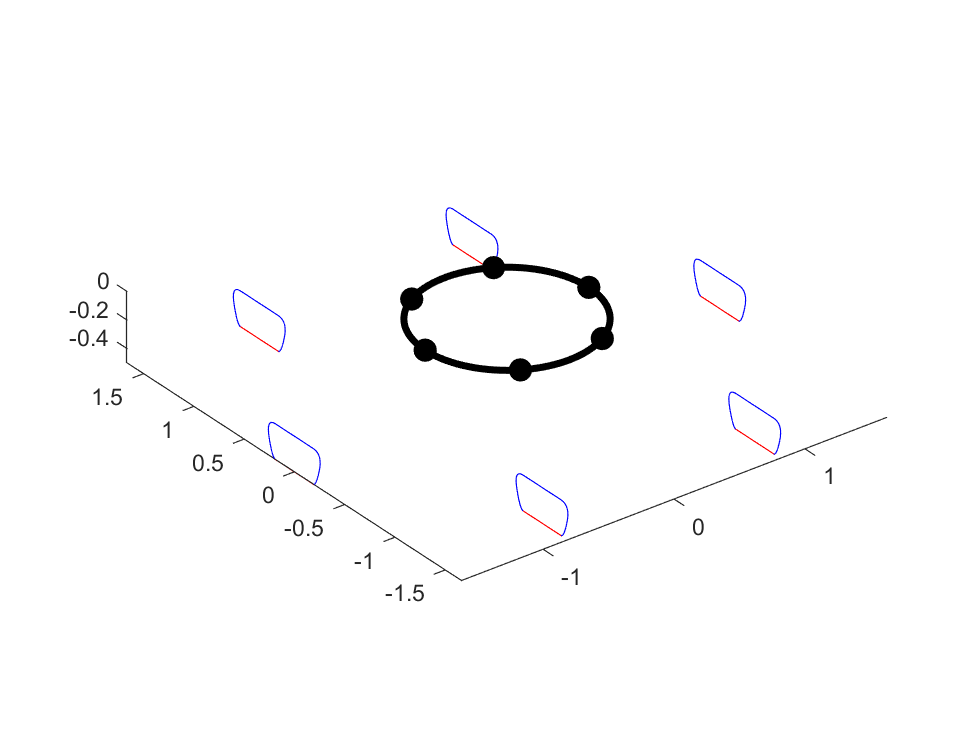

    s2 = [Rm*cos(1*beta), Rm*sin(1*beta), 0]';
    s3 = [Rm*cos(3*beta), Rm*sin(3*beta), 0]';
    s4 = [Rm*cos(0*beta), Rm*sin(0*beta), 0]';
    s5 = [Rm*cos(4*beta), Rm*sin(4*beta), 0]';
    s6 = [Rm*cos(5*beta), Rm*sin(5*beta), 0]';

    s = [s1, s2, s3, s4, s5, s6];
    scatter3(s(1,:),s(2,:),s(3,:),100,'filled',"MarkerFaceColor",'k')

function Rz = Rotz(theta)
%     theta = deg2rad(theta);
    Rz = [cos(theta) -sin(theta) 0;
          sin(theta)  cos(theta) 0
          0 0 1];
end

function Rx = Rotx(theta)
%     theta = deg2rad(theta);
    Rx = [1 0 0;
          0  cos(theta) -sin(theta)
          0 sin(theta) cos(theta)];
end

function plotCircle(Rm,h)
    th = linspace(0,360);
    cir_x = Rm*cosd(th);
    cir_y = Rm*sind(th);
    cir_z = h*ones(length(cir_x),1)';
    plot3(cir_x,cir_y, cir_z,"Color",'k',"LineWidth",3)
end
